# Find largest visible AprilTag in an img

## Initialize ros and take care of path:

init_matlab();

path added!
Shutting down global node /matlab_global_node_03445 with NodeURI http://192.168.16.78:63693/ and MasterURI http://192.168.16.71:11311/.
Initializing global node /matlab_global_node_23841 with NodeURI http://192.168.16.78:63765/ and MasterURI http://192.168.16.71:11311/.
ROS initialization complete! :-)


## Create cam object

calib_params = load("camera_calibration/calib_1024x768/cameraParams2.mat");
cam_intrinsics = calib_params.cameraParams2.Intrinsics;
cam = Camera_ROS(cam_intrinsics);

## Display image with tag overlays

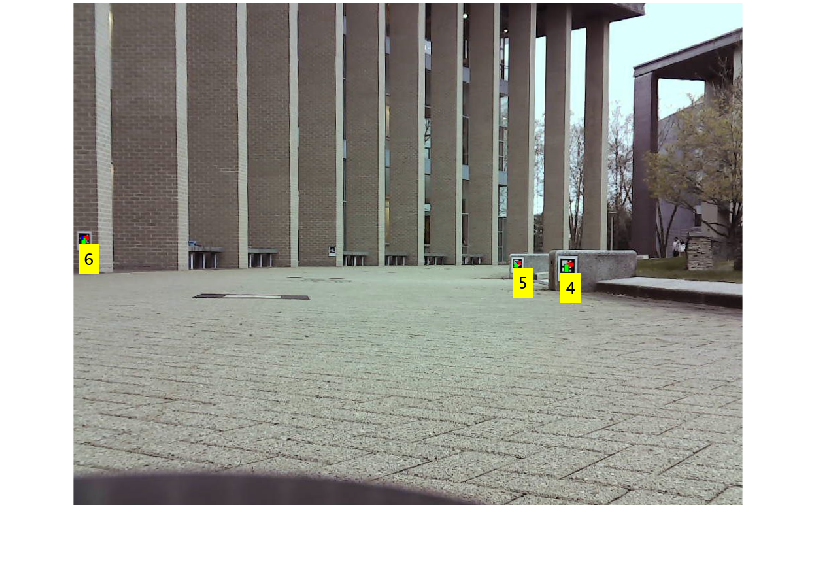

img = imread("testing/tag_images/beforebridge_0.55pwm_3.png");
% img = rgb2gray(cam.get_image_raw());

[img_undistort, new_center] = cam.undistort_image(img);
[num_tags, tag_ids, tag_img_corners, rigid3ds] = AprilTags.detect_tags_in_image(img_undistort, cam.camera_intrinsics);

img_tags_draw = AprilTags.draw_tags_on_image(img_undistort, cam.camera_intrinsics, num_tags, tag_ids, tag_img_corners, rigid3ds);
figure
imshow(img_tags_draw);

## Find tag id of largest tag

[~, largest_tag_id] = get_largest_tag(num_tags, tag_ids, tag_img_corners, rigid3ds)

largest_tag_id = 4

function [largest_tag_rigid3d, largest_tag_id] = get_largest_tag(num_tags, tag_ids, tag_img_corners, rigid3ds)
    % takes a list of tag image corners and returns the index of the
    % largest size tag in that list
    tag_areas = zeros(1, num_tags);
    for i = 1:num_tags
        tag_areas(i) = polyarea(tag_img_corners(:,1,i), tag_img_corners(:,2,i));
    end
    
    % find index of largest tag
    [~, idx_largest] = max(tag_areas);

    % get detected rigid3d from that index
    largest_tag_rigid3d = rigid3ds(idx_largest);
    largest_tag_id = tag_ids(idx_largest);
end